T = 1:400;
N = 10;
tmin = 25;
t0 = 1;
u = binrand(T, N, tmin, t0, 'normal');

x =     0.0000    0.0001    0.0004    0.0011    0.0025    0.0057    0.0118    0.0231    0.0424    0.0730    0.1180    0.1800    0.2591    0.3531    0.4571    0.5642    0.6667    0.7581    0.8339    0.8923    0.9342    0.9623    0.9797    0.9898    0.9952    0.9979    0.9991    0.9997    0.9999    1.0000


x =     0.0000    0.0001    0.0004    0.0011    0.0025    0.0057    0.0118    0.0231    0.0424    0.0730    0.1180    0.1800    0.2591    0.3531    0.4571    0.5642    0.6667    0.7581    0.8339    0.8923    0.9342    0.9623    0.9797    0.9898    0.9952    0.9979    0.9991    0.9997    0.9999    1.0000


x =     0.0000    0.0001    0.0004    0.0011    0.0025    0.0057    0.0118    0.0231    0.0424    0.0730    0.1180    0.1800    0.2591    0.3531    0.4571    0.5642    0.6667    0.7581    0.8339    0.8923    0.9342    0.9623    0.9797    0.9898    0.9952    0.9979    0.9991    0.9997    0.9999    1.0000


x =     0.0000    0.0001    0.0004    0.0011    0.0025    0.0057    0.0118    0.0231    0.0424    0.0730    0.1180    0.1800    0.2591    0.3531    0.4571    0.5642    0.6667    0.7581    0.8339    0.8923    0.9342    0.9623    0.9797    0.9898    0.9952    0.9979    0.9991    0.9997    0.9999    1.0000


x =     0.0000    0.0001    0.0004    0.0011    0.0025    0.0057    0.0118    0.0231    0.0424    0.0730    0.1180    0.1800    0.2591    0.3531    0.4571    0.5642    0.6667    0.7581    0.8339    0.8923    0.9342    0.9623    0.9797    0.9898    0.9952    0.9979    0.9991    0.9997    0.9999    1.0000


x =     0.0000    0.0001    0.0004    0.0011    0.0025    0.0057    0.0118    0.0231    0.0424    0.0730    0.1180    0.1800    0.2591    0.3531    0.4571    0.5642    0.6667    0.7581    0.8339    0.8923    0.9342    0.9623    0.9797    0.9898    0.9952    0.9979    0.9991    0.9997    0.9999    1.0000


x =     0.0000    0.0001    0.0004    0.0011    0.0025    0.0057    0.0118    0.0231    0.0424    0.0730    0.1180    0.1800    0.2591    0.3531    0.4571    0.5642    0.6667    0.7581    0.8339    0.8923    0.9342    0.9623    0.9797    0.9898    0.9952    0.9979    0.9991    0.9997    0.9999    1.0000


x =     0.0000    0.0001    0.0004    0.0011    0.0025    0.0057    0.0118    0.0231    0.0424    0.0730    0.1180    0.1800    0.2591    0.3531    0.4571    0.5642    0.6667    0.7581    0.8339    0.8923    0.9342    0.9623    0.9797    0.9898    0.9952    0.9979    0.9991    0.9997    0.9999    1.0000


x =     0.0000    0.0001    0.0004    0.0011    0.0025    0.0057    0.0118    0.0231    0.0424    0.0730    0.1180    0.1800    0.2591    0.3531    0.4571    0.5642    0.6667    0.7581    0.8339    0.8923    0.9342    0.9623    0.9797    0.9898    0.9952    0.9979    0.9991    0.9997    0.9999    1.0000


% Define the transfer functions
numerator = [1, 0];
denominator = [10, -10];
ts = 0.01;
C = tf(numerator, denominator, ts);

num = [0.1812];
den = [1, -0.8187];
G = tf(num, den, ts);

variance1 = 0.1; % also for 0.01 and 0.001
variance2 = 0.01;
variance3 = 0.001;
noise1 = sqrt(variance1) * randn(size(u));
noise2 = sqrt(variance2) * randn(size(u));
noise3 = sqrt(variance3) * randn(size(u));

Ts = 0.01;                % Sample time of the models
N = length(u); 
timeVector = 0:Ts:(N-1)*Ts;

output1 = lsim((G*C)/(1+(G*C)), u.', timeVector.') + lsim(1/(1+C*G), noise1.', timeVector.');
output2 = lsim((G*C)/(1+(G*C)), u.', timeVector.') + lsim(1/(1+C*G), noise2.', timeVector.');
output3 = lsim((G*C)/(1+(G*C)), u.', timeVector.') + lsim(1/(1+C*G), noise3.', timeVector.');

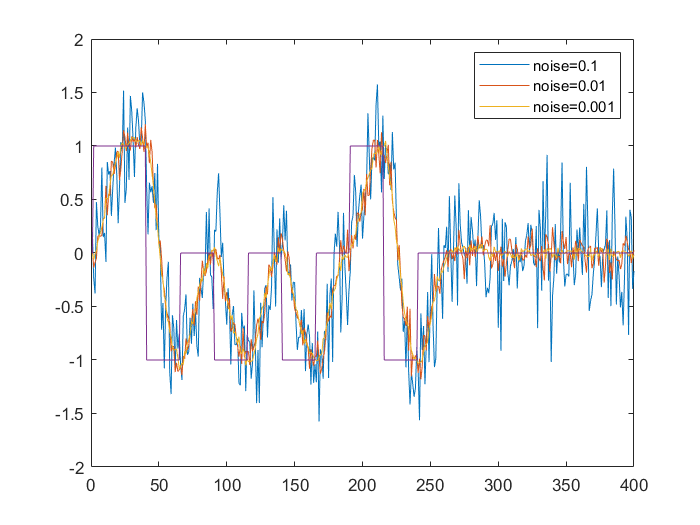

figure;
plot(output1)
hold on
plot(output2)
plot(output3)
plot(u)
legend('noise=0.1','noise=0.01', 'noise=0.001');
hold off

pairs1 = table(u.', output1, 'VariableNames', {'Input', 'Output'});
pairs2 = table(u.', output2, 'VariableNames', {'Input', 'Output'});
pairs3 = table(u.', output3, 'VariableNames', {'Input', 'Output'});

% Define a range of values for na, nb, and nk
na_values = [1, 2, 3, 4];   % List of 'na' values to test
nb_values = [1, 2, 3, 4];   % List of 'nb' values to test
nd_values = [1, 2, 3, 4];   % List of 'nd' values to test
nk_values = [0, 1, 2, 3, 4];   % List of 'nk' values to test
best_na = 0;                % Variable to store the best 'na' value
best_nb = 0;                % Variable to store the best 'nb' value
best_nd = 0;                % Variable to store the best 'nd' value
best_nk = 0;                % Variable to store the best 'nk' value
best_val_error = Inf;       % Variable to store the best validation error
best_model = [];            % Variable to store the best model
best_y_pred = [];  
% Loop over each combination of 'na', 'nb', 'nd', and 'nk' values
for na = na_values
    for nb = nb_values
        for nd = nd_values
            for nk = nk_values
                % PEM Model Identification
                model = pem(iddata(output1, u.', 0.01), 'na', na, 'nb', nb, 'nd', nd, 'nk', nk);
                y_val_pred = sim(model, iddata(output1, u.', 0.01));
                val_error = mean((y_val_pred.OutputData - output1).^2);
                if val_error < best_val_error
                    best_val_error = val_error;
                    best_na = na;
                    best_nb = nb;
                    best_nd = nd;
                    best_nk = nk;
                    best_model = model;  % Store the best model
                    best_y_pred = y_val_pred.OutputData;
                end
            end
        end
    end
end

% Display the best parameter values and validation error
disp(['Best na value: ', num2str(best_na)]);

Best na value: 4


disp(['Best nb value: ', num2str(best_nb)]);

Best nb value: 4


disp(['Best nd value: ', num2str(best_nd)]);

Best nd value: 4


disp(['Best nk value: ', num2str(best_nk)]);

Best nk value: 4


disp(['Best validation error (MSE): ', num2str(best_val_error)]);

Best validation error (MSE): 0.11169



% Display the best model
disp('Best model:');

Best model:


disp(best_model);

  idpoly with properties:

                 A: [1 0.0316 -0.7382 -0.1460 0.1473]
                 B: [0 0 0 0 0.1535 -0.1379 -0.1303 0.4026]
                 C: 1
                 D: [1 -0.2410 0.6694 -0.0513 0.2768]
                 F: 1
    IntegrateNoise: 0
          Variable: 'z^-1'
           IODelay: 0
         Structure: [1×1 pmodel.polynomial]
     NoiseVariance: 0.1165
            Report: [1×1 idresults.polyest]
        InputDelay: 0
       OutputDelay: 0
                Ts: 0.0100
          TimeUnit: 'seconds'
         InputName: {'u1'}
         InputUnit: {''}
        InputGroup: [1×1 struct]
        OutputName: {'y1'}
        OutputUnit: {''}
       OutputGroup: [1×1 struct]
             Notes: [0×1 string]
          UserData: []
              Name: ''
      SamplingGrid: [1×1 struct]



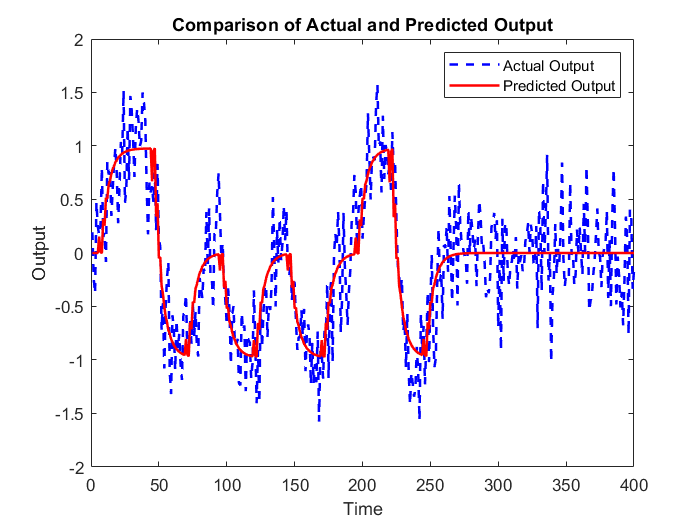

% Plot the actual output and predicted output
figure;
t = 1:length(output1);
plot(t, output1, 'b--', 'LineWidth', 1.5);
hold on;
plot(t, best_y_pred, 'r', 'LineWidth', 1.5);
hold off;
xlabel('Time');
ylabel('Output');
legend('Actual Output', 'Predicted Output');
title('Comparison of Actual and Predicted Output');

best_model

best_model =
Discrete-time ARARX model: A(z)y(t) = B(z)u(t) + [1/D(z)]e(t)     
  A(z) = 1 + 0.03162 z^-1 - 0.7382 z^-2 - 0.146 z^-3 + 0.1473 z^-4
                                                                  
  B(z) = 0.1535 z^-4 - 0.1379 z^-5 - 0.1303 z^-6 + 0.4026 z^-7    
                                                                  
  D(z) = 1 - 0.241 z^-1 + 0.6694 z^-2 - 0.05126 z^-3 + 0.2768 z^-4
                                                                  
Sample time: 0.01 seconds
  
Parameterization:
   Polynomial orders:   na=4   nb=4   nd=4   nk=4
   Number of free coefficients: 12
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using PEM on time domain data.         
Fit to estimation data: 47.67% (prediction focus)
FPE: 0.12, MSE: 0.113                            


% Extract zeros and poles from the estimated ARX model
zeros_est = zero(best_model);
poles_est = pole(best_model);

% Display the zero locations and poles
disp('Estimated Model:');

Estimated Model:


disp('Zeros:');

Zeros:


disp(zeros_est);

   1.1000 + 0.8973i
   1.1000 - 0.8973i
  -1.3017 + 0.0000i



disp('Poles:');

Poles:


disp(poles_est);

  -0.6237 + 0.2538i
  -0.6237 - 0.2538i
   0.8191 + 0.0000i
   0.3966 + 0.0000i



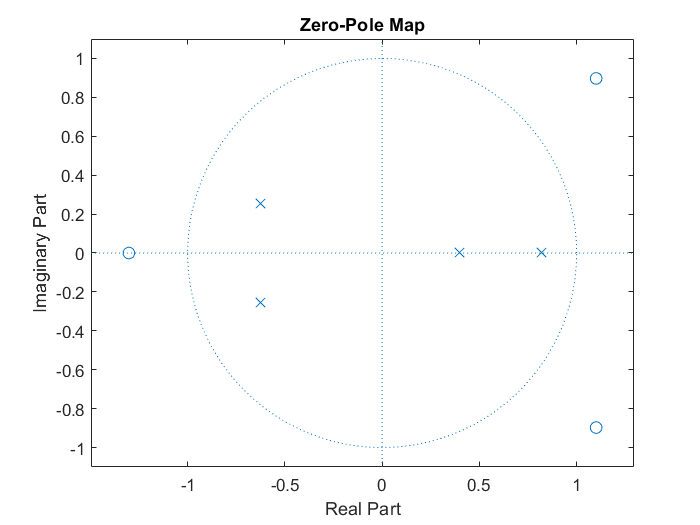


% Plot the zero-pole map
figure;
zplane(zeros_est, poles_est);
title('Zero-Pole Map');

e = u.' - best_y_pred;
corr_eu = corrcoef(e, u.');
corr_eu = corr_eu(1, 2); % Extract the correlation coefficient from the matrix

% Calculate the correlation between e and y
corr_ey = corrcoef(e, best_y_pred);
corr_ey = corr_ey(1, 2); % Extract the correlation coefficient from the matrix

% Display the correlation coefficients
disp('Correlation between e and u:');

Correlation between e and u:


disp(corr_eu);

    0.6171



disp('Correlation between e and y:');

Correlation between e and y:


disp(corr_ey);

   -0.3473



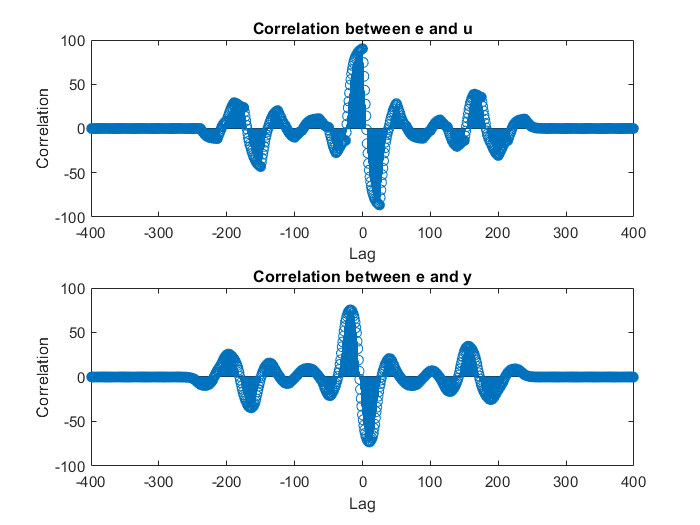


corr_eu = xcorr(e, u.');

% Calculate the correlation between e and y
corr_ey = xcorr(e, best_y_pred);

% Plot the correlation results
lags = -(length(e)-1):(length(e)-1);
figure;
subplot(2, 1, 1);
stem(lags, corr_eu);
title('Correlation between e and u');
xlabel('Lag');
ylabel('Correlation');
subplot(2, 1, 2);
stem(lags, corr_ey);
title('Correlation between e and y');
xlabel('Lag');
ylabel('Correlation');

% Define a range of values for na, nb, and nk
na_values = [1, 2, 3, 4];   % List of 'na' values to test
nb_values = [1, 2, 3, 4];   % List of 'nb' values to test
nd_values = [1, 2, 3, 4];   % List of 'nd' values to test
nk_values = [0, 1, 2, 3, 4];   % List of 'nk' values to test
best_na = 0;                % Variable to store the best 'na' value
best_nb = 0;                % Variable to store the best 'nb' value
best_nd = 0;                % Variable to store the best 'nd' value
best_nk = 0;                % Variable to store the best 'nk' value
best_val_error = Inf;       % Variable to store the best validation error
best_model = [];            % Variable to store the best model
best_y_pred = [];  
% Loop over each combination of 'na', 'nb', 'nd', and 'nk' values
for na = na_values
    for nb = nb_values
        for nd = nd_values
            for nk = nk_values
                % PEM Model Identification
                model = pem(iddata(output2, u.', 0.01), 'na', na, 'nb', nb, 'nd', nd, 'nk', nk);
                y_val_pred = sim(model, iddata(output2, u.', 0.01));
                val_error = mean((y_val_pred.OutputData - output2).^2);
                if val_error < best_val_error
                    best_val_error = val_error;
                    best_na = na;
                    best_nb = nb;
                    best_nd = nd;
                    best_nk = nk;
                    best_model = model;  % Store the best model
                    best_y_pred = y_val_pred.OutputData;
                end
            end
        end
    end
end

% Display the best parameter values and validation error
disp(['Best na value: ', num2str(best_na)]);

Best na value: 2


disp(['Best nb value: ', num2str(best_nb)]);

Best nb value: 4


disp(['Best nd value: ', num2str(best_nd)]);

Best nd value: 4


disp(['Best nk value: ', num2str(best_nk)]);

Best nk value: 4


disp(['Best validation error (MSE): ', num2str(best_val_error)]);

Best validation error (MSE): 0.013757



% Display the best model
disp('Best model:');

Best model:


disp(best_model);

  idpoly with properties:

                 A: [1 -1.0669 0.1653]
                 B: [0 0 0 0 0.1088 -0.0579 -6.5319e-04 0.0545]
                 C: 1
                 D: [1 0.8661 0.5835 0.4133 0.2308]
                 F: 1
    IntegrateNoise: 0
          Variable: 'z^-1'
           IODelay: 0
         Structure: [1×1 pmodel.polynomial]
     NoiseVariance: 0.0134
            Report: [1×1 idresults.polyest]
        InputDelay: 0
       OutputDelay: 0
                Ts: 0.0100
          TimeUnit: 'seconds'
         InputName: {'u1'}
         InputUnit: {''}
        InputGroup: [1×1 struct]
        OutputName: {'y1'}
        OutputUnit: {''}
       OutputGroup: [1×1 struct]
             Notes: [0×1 string]
          UserData: []
              Name: ''
      SamplingGrid: [1×1 struct]



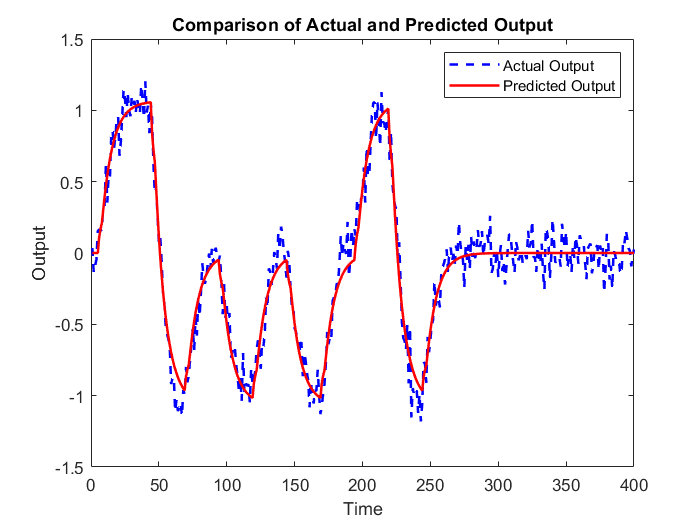

% Plot the actual output and predicted output
figure;
t = 1:length(output2);
plot(t, output2, 'b--', 'LineWidth', 1.5);
hold on;
plot(t, best_y_pred, 'r', 'LineWidth', 1.5);
hold off;
xlabel('Time');
ylabel('Output');
legend('Actual Output', 'Predicted Output');
title('Comparison of Actual and Predicted Output');

best_model

best_model =
Discrete-time ARARX model: A(z)y(t) = B(z)u(t) + [1/D(z)]e(t)      
  A(z) = 1 - 1.067 z^-1 + 0.1653 z^-2                              
                                                                   
  B(z) = 0.1088 z^-4 - 0.05789 z^-5 - 0.0006532 z^-6 + 0.05446 z^-7
                                                                   
  D(z) = 1 + 0.8661 z^-1 + 0.5835 z^-2 + 0.4133 z^-3 + 0.2308 z^-4 
                                                                   
Sample time: 0.01 seconds
  
Parameterization:
   Polynomial orders:   na=2   nb=4   nd=4   nk=4
   Number of free coefficients: 10
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using PEM on time domain data.         
Fit to estimation data: 79.23% (prediction focus)
FPE: 0.01372, MSE: 0.01305                       


% Extract zeros and poles from the estimated ARX model
zeros_est = zero(best_model);
poles_est = pole(best_model);

% Display the zero locations and poles
disp('Estimated Model:');

Estimated Model:


disp('Zeros:');

Zeros:


disp(zeros_est);

   0.5922 + 0.6451i
   0.5922 - 0.6451i
  -0.6525 + 0.0000i



disp('Poles:');

Poles:


disp(poles_est);

         0
         0
    0.8788
    0.1880



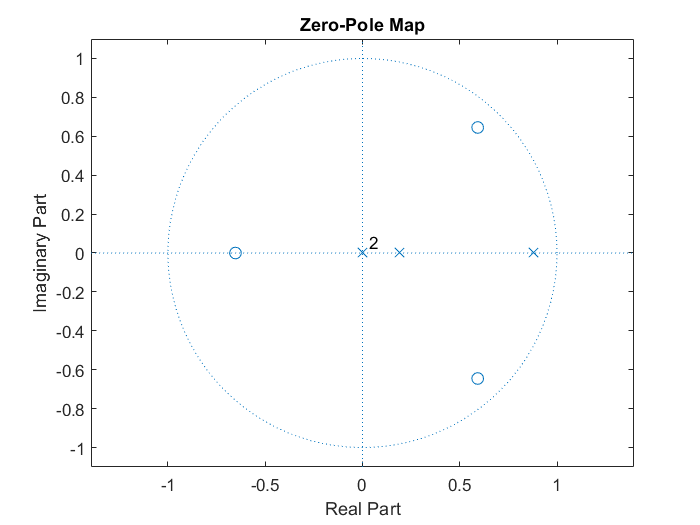


% Plot the zero-pole map
figure;
zplane(zeros_est, poles_est);
title('Zero-Pole Map');

e = u.' - best_y_pred;
corr_eu = corrcoef(e, u.');
corr_eu = corr_eu(1, 2); % Extract the correlation coefficient from the matrix

% Calculate the correlation between e and y
corr_ey = corrcoef(e, best_y_pred);
corr_ey = corr_ey(1, 2); % Extract the correlation coefficient from the matrix

% Display the correlation coefficients
disp('Correlation between e and u:');

Correlation between e and u:


disp(corr_eu);

    0.6197



disp('Correlation between e and y:');

Correlation between e and y:


disp(corr_ey);

   -0.3422



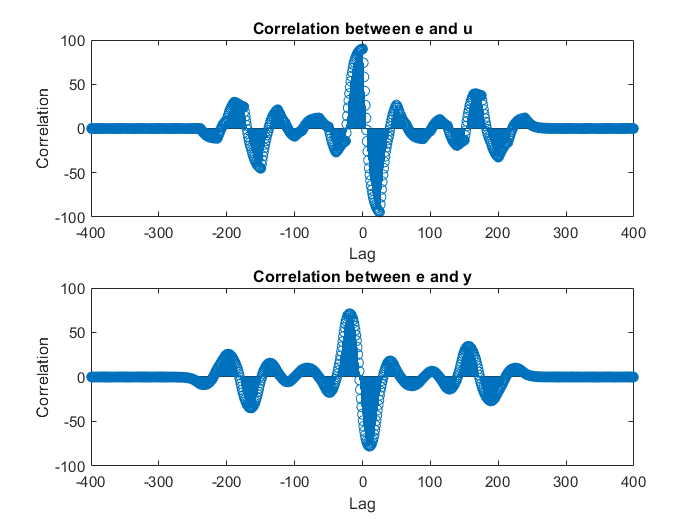


corr_eu = xcorr(e, u.');

% Calculate the correlation between e and y
corr_ey = xcorr(e, best_y_pred);

% Plot the correlation results
lags = -(length(e)-1):(length(e)-1);
figure;
subplot(2, 1, 1);
stem(lags, corr_eu);
title('Correlation between e and u');
xlabel('Lag');
ylabel('Correlation');
subplot(2, 1, 2);
stem(lags, corr_ey);
title('Correlation between e and y');
xlabel('Lag');
ylabel('Correlation');

% Define a range of values for na, nb, and nk
na_values = [1, 2, 3, 4];   % List of 'na' values to test
nb_values = [1, 2, 3, 4];   % List of 'nb' values to test
nd_values = [1, 2, 3, 4];   % List of 'nd' values to test
nk_values = [0, 1, 2, 3, 4];   % List of 'nk' values to test
best_na = 0;                % Variable to store the best 'na' value
best_nb = 0;                % Variable to store the best 'nb' value
best_nd = 0;                % Variable to store the best 'nd' value
best_nk = 0;                % Variable to store the best 'nk' value
best_val_error = Inf;       % Variable to store the best validation error
best_model = [];            % Variable to store the best model
best_y_pred = [];  
% Loop over each combination of 'na', 'nb', 'nd', and 'nk' values
for na = na_values
    for nb = nb_values
        for nd = nd_values
            for nk = nk_values
                % PEM Model Identification
                model = pem(iddata(output3, u.', 0.01), 'na', na, 'nb', nb, 'nd', nd, 'nk', nk);
                y_val_pred = sim(model, iddata(output3, u.', 0.01));
                val_error = mean((y_val_pred.OutputData - output3).^2);
                if val_error < best_val_error
                    best_val_error = val_error;
                    best_na = na;
                    best_nb = nb;
                    best_nd = nd;
                    best_nk = nk;
                    best_model = model;  % Store the best model
                    best_y_pred = y_val_pred.OutputData;
                end
            end
        end
    end
end

% Display the best parameter values and validation error
disp(['Best na value: ', num2str(best_na)]);

Best na value: 4


disp(['Best nb value: ', num2str(best_nb)]);

Best nb value: 2


disp(['Best nd value: ', num2str(best_nd)]);

Best nd value: 4


disp(['Best nk value: ', num2str(best_nk)]);

Best nk value: 0


disp(['Best validation error (MSE): ', num2str(best_val_error)]);

Best validation error (MSE): 0.0013251



% Display the best model
disp('Best model:');

Best model:


disp(best_model);

  idpoly with properties:

                 A: [1 -2.3211 2.3313 -1.4581 0.4665]
                 B: [-0.0073 0.0260]
                 C: 1
                 D: [1 1.9808 1.9022 1.0512 0.2858]
                 F: 1
    IntegrateNoise: 0
          Variable: 'z^-1'
           IODelay: 0
         Structure: [1×1 pmodel.polynomial]
     NoiseVariance: 0.0016
            Report: [1×1 idresults.polyest]
        InputDelay: 0
       OutputDelay: 0
                Ts: 0.0100
          TimeUnit: 'seconds'
         InputName: {'u1'}
         InputUnit: {''}
        InputGroup: [1×1 struct]
        OutputName: {'y1'}
        OutputUnit: {''}
       OutputGroup: [1×1 struct]
             Notes: [0×1 string]
          UserData: []
              Name: ''
      SamplingGrid: [1×1 struct]



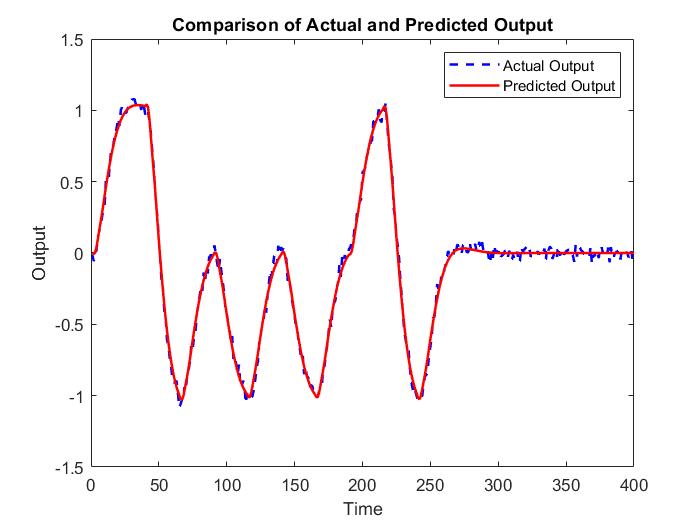

% Plot the actual output and predicted output
figure;
t = 1:length(output3);
plot(t, output3, 'b--', 'LineWidth', 1.5);
hold on;
plot(t, best_y_pred, 'r', 'LineWidth', 1.5);
hold off;
xlabel('Time');
ylabel('Output');
legend('Actual Output', 'Predicted Output');
title('Comparison of Actual and Predicted Output');

best_model

best_model =
Discrete-time ARARX model: A(z)y(t) = B(z)u(t) + [1/D(z)]e(t)  
  A(z) = 1 - 2.321 z^-1 + 2.331 z^-2 - 1.458 z^-3 + 0.4665 z^-4
                                                               
  B(z) = -0.007322 + 0.02603 z^-1                              
                                                               
  D(z) = 1 + 1.981 z^-1 + 1.902 z^-2 + 1.051 z^-3 + 0.2858 z^-4
                                                               
Sample time: 0.01 seconds
  
Parameterization:
   Polynomial orders:   na=4   nb=2   nd=4   nk=0
   Number of free coefficients: 10
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using PEM on time domain data.         
Fit to estimation data: 92.73% (prediction focus)
FPE: 0.00161, MSE: 0.001531                      


% Extract zeros and poles from the estimated ARX model
zeros_est = zero(best_model);
poles_est = pole(best_model);

% Display the zero locations and poles
disp('Estimated Model:');

Estimated Model:


disp('Zeros:');

Zeros:


disp(zeros_est);

         0
         0
         0
    3.5552



disp('Poles:');

Poles:


disp(poles_est);

   0.2632 + 0.7106i
   0.2632 - 0.7106i
   0.8973 + 0.0851i
   0.8973 - 0.0851i



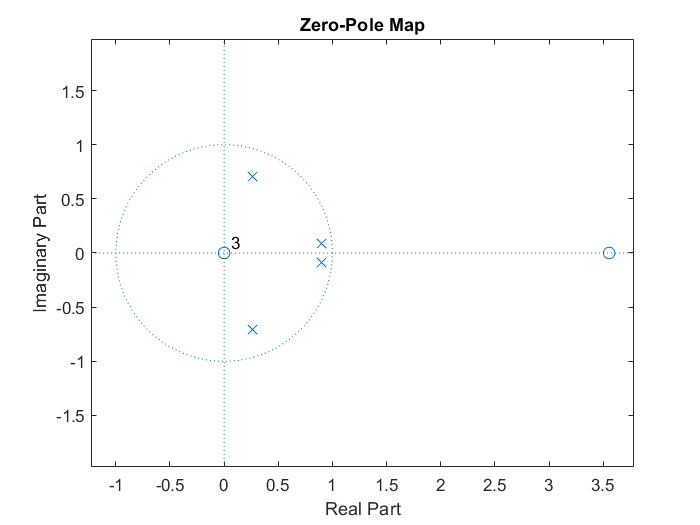


% Plot the zero-pole map
figure;
zplane(zeros_est, poles_est);
title('Zero-Pole Map');

e = u.' - best_y_pred;
corr_eu = corrcoef(e, u.');
corr_eu = corr_eu(1, 2); % Extract the correlation coefficient from the matrix

% Calculate the correlation between e and y
corr_ey = corrcoef(e, best_y_pred);
corr_ey = corr_ey(1, 2); % Extract the correlation coefficient from the matrix

% Display the correlation coefficients
disp('Correlation between e and u:');

Correlation between e and u:


disp(corr_eu);

    0.6125



disp('Correlation between e and y:');

Correlation between e and y:


disp(corr_ey);

   -0.3295



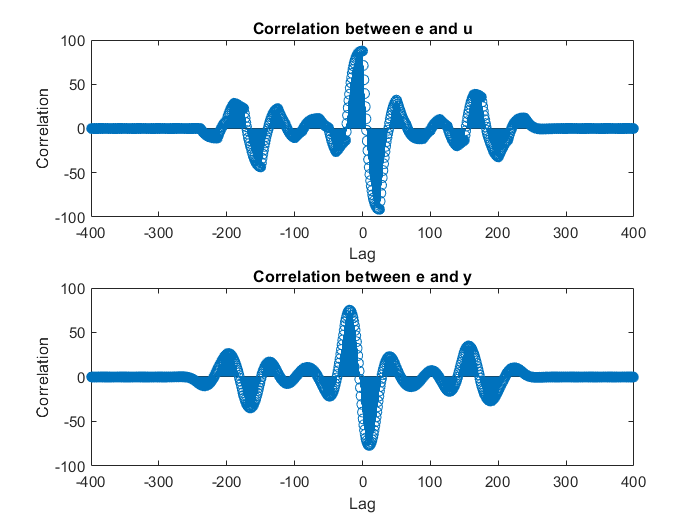


corr_eu = xcorr(e, u.');

% Calculate the correlation between e and y
corr_ey = xcorr(e, best_y_pred);

% Plot the correlation results
lags = -(length(e)-1):(length(e)-1);
figure;
subplot(2, 1, 1);
stem(lags, corr_eu);
title('Correlation between e and u');
xlabel('Lag');
ylabel('Correlation');
subplot(2, 1, 2);
stem(lags, corr_ey);
title('Correlation between e and y');
xlabel('Lag');
ylabel('Correlation');

% % Calculate the maximum lag value
% maxlag = max([na_values, nb_values, nc_values]);
% 
% % Loop over each combination of 'na', 'nb', 'nc', and 'nk' values
% for na = na_values
%     for nb = nb_values
%         for nc = nc_values
%             for nk = nk_values
%                 % Create the regressor matrix
%                 Phi = [];
%                 for k = maxlag + nk + 1:length(output1)
%                     phi_k = -output1(k-1:-1:k-na); % AR coefficients
%                     phi_k = [phi_k; u(k-1:-1:k-nb)]; % X coefficients
%                     phi_k = [phi_k; output1(k-1:-1:k-nc)]; % Y coefficients
%                     Phi = [Phi; phi_k'];
%                 end
% 
%                 % Create the output vector
%                 Y = output1(maxlag + nk + 1:end);
% 
%                 % Solve the GLS problem
%                 theta = (Phi' * Phi) \ Phi' * Y;
% 
%                 % Create the ARMAX model
%                 A = [1, theta(1:na)];
%                 B = [theta(na+1:na+nb); 1];
%                 C = [theta(na+nb+1:na+nb+nc)];
%                 D = 1;
%                 K = [theta(na+nb+nc+1:end); zeros(nk, 1)];
%                 sys = idpoly(A, B, C, D, K, 'Ts', 0.01);
% 
%                 % Compare model output with validation data
%                 y_val_pred = filter(sys, 1, u);
%                 y_val_pred = y_val_pred.OutputData;
%                 val_error = mean((y_val_pred - output1(maxlag + nk + 1:end)).^2);
% 
%                 % Update best model if validation error improves
%                 if val_error < best_val_error
%                     best_val_error = val_error;
%                     best_na = na;
%                     best_nb = nb;
%                     best_nc = nc;
%                     best_nk = nk;
%                     best_model = sys;
%                     best_y_pred = y_val_pred;
%                 end
%             end
%         end
%     end
% end
% 
% % Display the best parameter values and validation error
% disp(['Best na value: ', num2str(best_na)]);
% disp(['Best nb value: ', num2str(best_nb)]);
% disp(['Best nc value: ', num2str(best_nc)]);
% disp(['Best nk value: ', num2str(best_nk)]);
% disp(['Best validation error (MSE): ', num2str(best_val_error)]);
% 
% % Display the best model
% disp('Best model:');
% disp(best_model);

% function [best_model, best_y_pred] = ararx_identification(output, u, na_values, nb_values, nc_values, nk_values)
%     best_val_error = inf;
%     best_na = 0;
%     best_nb = 0;
%     best_nc = 0;
%     best_nk = 0;
%     best_model = [];
%     best_y_pred = [];
% 
%     % Loop over each combination of 'na', 'nb', 'nc', and 'nk' values
%     for na = na_values
%         for nb = nb_values
%             for nc = nc_values
%                 for nk = nk_values
%                     % Construct the Hankel matrix
%                     num_samples = length(output);
%                     Hankel = zeros(num_samples - nc - nk + 1, nb + nc);
%                     for i = 1:nb + nc
%                         Hankel(:, i) = output(nc + nk - 1 - i + 1:num_samples - i + 1);
%                     end
% 
%                     % Construct the regressor matrix
%                     Regressor = zeros(num_samples - nc - nk + 1, na + nb + nc);
%                     for i = 1:na + nb + nc
%                         if i <= na
%                             Regressor(:, i) = -output(nc + nk - 1 - i + 1:num_samples - nc - nk + 1 - i + 1);
%                         elseif i <= na + nb
%                             Regressor(:, i) = u(nk - 1 - i + na + 1:num_samples - nc - i + na + 1);
%                         else
%                             Regressor(:, i) = output(nc + nk - 1 - i - nb + 1:num_samples - nc - nk + 1 - i - nb + 1);
%                         end
%                     end
% 
%                     % Estimate the model coefficients using GLS
%                     theta = (Regressor' * Regressor) \ (Regressor' * Hankel);
% 
%                     % Construct the ARARX model
%                     A = [1; theta(1:na)];
%                     B = theta(na+1:na+nb);
%                     C = [1; theta(na+nb+1:na+nb+nc)];
%                     D = 1;
%                     F = [1; theta(na+nb+nc+1:na+nb+nc+nk)];
%                     sys = idpoly(A, B, C, D, F, 'Ts', 1);
% 
%                     % Evaluate the model performance on validation data
%                     y_val_pred = sim(sys, iddata(output(nc + nk:end), u(nk:end), 1));
%                     val_error = mean((y_val_pred.OutputData - output(nc + nk:end)).^2);
% 
%                     % Update the best model if the validation error improves
%                     if val_error < best_val_error
%                         best_val_error = val_error;
%                         best_na = na;
%                         best_nb = nb;
%                         best_nc = nc;
%                         best_nk = nk;
%                         best_model = sys;
%                         best_y_pred = y_val_pred.OutputData;
%                     end
%                 end
%             end
%         end
%     end
% 
%     % Display the best parameter values and validation error
%     disp(['Best na value: ', num2str(best_na)]);
%     disp(['Best nb value: ', num2str(best_nb)]);
%     disp(['Best nc value: ', num2str(best_nc)]);
%     disp(['Best nk value: ', num2str(best_nk)]);
%     disp(['Best validation error (MSE): ', num2str(best_val_error)]);
% 
%     % Display the best model
%     disp('Best model:');
%     disp(best_model);
% end
% 
% function y_pred = simulate_ararx_model(sys, output, u, nc, nk)
%     num_samples = length(output);
%     y_pred = zeros(num_samples - nc + 1, 1);
%     for k = nc:num_samples
%         y_pred(k - nc + 1) = sys.C * output(k:-1:k - nc + 1) + sys.D * u(k - nk + 1) + sys.F * output(k - nk);
%     end
% end

% Define a range of values for na, nb, and nk
na_values = [1, 2, 3, 4];   % List of 'na' values to test
nb_values = [1, 2, 3, 4];   % List of 'nb' values to test
nd_values = [1, 2, 3, 4];   % List of 'nd' values to test
nk_values = [0, 1, 2, 3, 4];   % List of 'nk' values to test
best_na = 0;                % Variable to store the best 'na' value
best_nb = 0;                % Variable to store the best 'nb' value
best_nd = 0;                % Variable to store the best 'nd' value
best_nk = 0;                % Variable to store the best 'nk' value
best_val_error = Inf;       % Variable to store the best validation error
best_model = [];            % Variable to store the best model
best_y_pred = [];  
% Loop over each combination of 'na', 'nb', 'nd', and 'nk' values
    for nb = nb_values
        for nd = nd_values
            for nk = nk_values
                % PEM Model Identification
                model = pem(iddata(output1, u.', 0.01), 'na', 1, 'nb', nb, 'nd', nd, 'nk', nk);
                y_val_pred = sim(model, iddata(output1, u.', 0.01));
                val_error = mean((y_val_pred.OutputData - output1).^2);
                if val_error < best_val_error
                    best_val_error = val_error;
                    best_na = na;
                    best_nb = nb;
                    best_nd = nd;
                    best_nk = nk;
                    best_model = model;  % Store the best model
                    best_y_pred = y_val_pred.OutputData;
                end
            end
        end
    end


% Display the best parameter values and validation error
disp(['Best na value: ', num2str(best_na)]);

Best na value: 4


disp(['Best nb value: ', num2str(best_nb)]);

Best nb value: 4


disp(['Best nd value: ', num2str(best_nd)]);

Best nd value: 4


disp(['Best nk value: ', num2str(best_nk)]);

Best nk value: 4


disp(['Best validation error (MSE): ', num2str(best_val_error)]);

Best validation error (MSE): 0.11276



% Display the best model
disp('Best model:');

Best model:


disp(best_model);

  idpoly with properties:

                 A: [1 -0.8001]
                 B: [0 0 0 0 0.1842 -0.2313 -0.0549 0.2949]
                 C: 1
                 D: [1 0.5889 0.3880 0.3143 0.1800]
                 F: 1
    IntegrateNoise: 0
          Variable: 'z^-1'
           IODelay: 0
         Structure: [1×1 pmodel.polynomial]
     NoiseVariance: 0.1176
            Report: [1×1 idresults.polyest]
        InputDelay: 0
       OutputDelay: 0
                Ts: 0.0100
          TimeUnit: 'seconds'
         InputName: {'u1'}
         InputUnit: {''}
        InputGroup: [1×1 struct]
        OutputName: {'y1'}
        OutputUnit: {''}
       OutputGroup: [1×1 struct]
             Notes: [0×1 string]
          UserData: []
              Name: ''
      SamplingGrid: [1×1 struct]



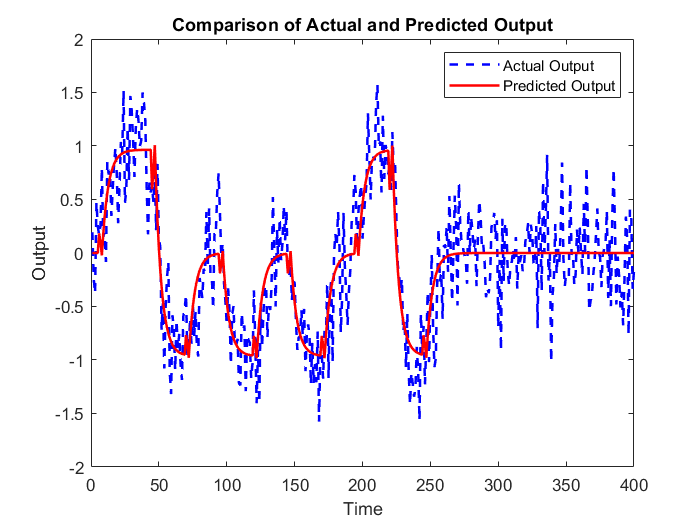

% Plot the actual output and predicted output
figure;
t = 1:length(output1);
plot(t, output1, 'b--', 'LineWidth', 1.5);
hold on;
plot(t, best_y_pred, 'r', 'LineWidth', 1.5);
hold off;
xlabel('Time');
ylabel('Output');
legend('Actual Output', 'Predicted Output');
title('Comparison of Actual and Predicted Output');

best_model

best_model =
Discrete-time ARARX model: A(z)y(t) = B(z)u(t) + [1/D(z)]e(t)  
  A(z) = 1 - 0.8001 z^-1                                       
                                                               
  B(z) = 0.1842 z^-4 - 0.2313 z^-5 - 0.05492 z^-6 + 0.2949 z^-7
                                                               
  D(z) = 1 + 0.5889 z^-1 + 0.388 z^-2 + 0.3143 z^-3 + 0.18 z^-4
                                                               
Sample time: 0.01 seconds
  
Parameterization:
   Polynomial orders:   na=1   nb=4   nd=4   nk=4
   Number of free coefficients: 9
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using PEM on time domain data.         
Fit to estimation data: 47.23% (prediction focus)
FPE: 0.1203, MSE: 0.115                          


% Extract zeros and poles from the estimated ARX model
zeros_est = zero(best_model);
poles_est = pole(best_model);

% Display the zero locations and poles
disp('Estimated Model:');

Estimated Model:


disp('Zeros:');

Zeros:


disp(zeros_est);

   1.0916 + 0.7314i
   1.0916 - 0.7314i
  -0.9274 + 0.0000i



disp('Poles:');

Poles:


disp(poles_est);

         0
         0
         0
    0.8001



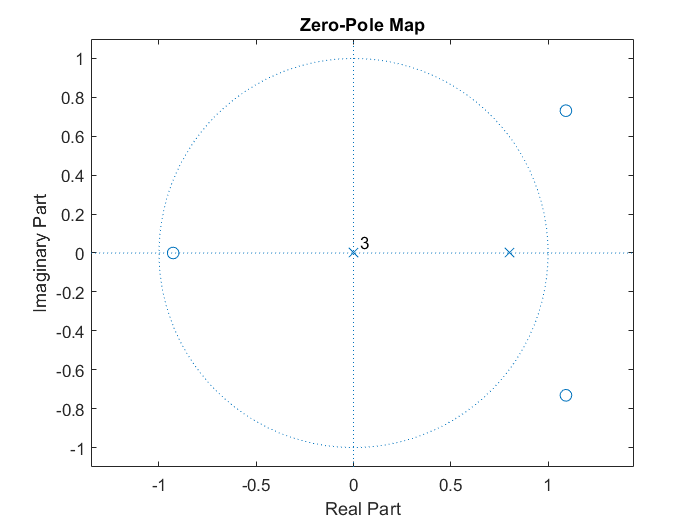


% Plot the zero-pole map
figure;
zplane(zeros_est, poles_est);
title('Zero-Pole Map');

e = u.' - best_y_pred;
corr_eu = corrcoef(e, u.');
corr_eu = corr_eu(1, 2); % Extract the correlation coefficient from the matrix

% Calculate the correlation between e and y
corr_ey = corrcoef(e, best_y_pred);
corr_ey = corr_ey(1, 2); % Extract the correlation coefficient from the matrix

% Display the correlation coefficients
disp('Correlation between e and u:');

Correlation between e and u:


disp(corr_eu);

    0.6136



disp('Correlation between e and y:');

Correlation between e and y:


disp(corr_ey);

   -0.3384



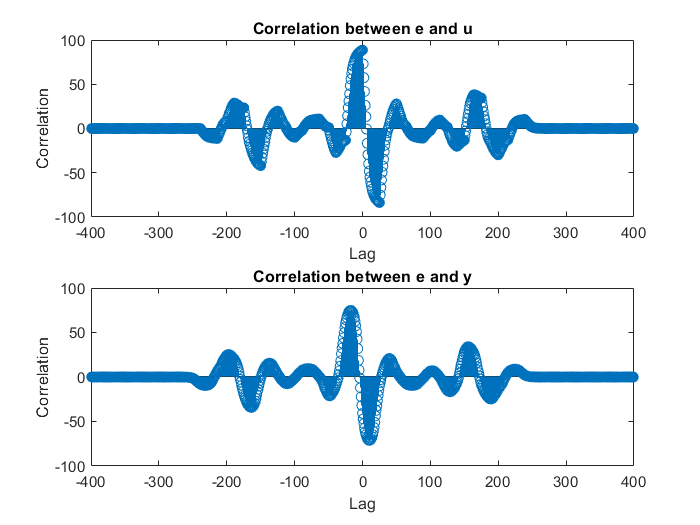


corr_eu = xcorr(e, u.');

% Calculate the correlation between e and y
corr_ey = xcorr(e, best_y_pred);

% Plot the correlation results
lags = -(length(e)-1):(length(e)-1);
figure;
subplot(2, 1, 1);
stem(lags, corr_eu);
title('Correlation between e and u');
xlabel('Lag');
ylabel('Correlation');
subplot(2, 1, 2);
stem(lags, corr_ey);
title('Correlation between e and y');
xlabel('Lag');
ylabel('Correlation');